#     Analyze heat capacity from DR

This routine is intended at analyzing Cp data acquired with our DR used in the Dynacool PPMS of the Lee lab

## To do: 

- Error bars:

-     For dT data, use standard deviation

-     For dCp values, add the SampHCErrmJmoleK field 

## Import data YTmVO4

% Data18 = ImportCpDR('2018-07-24_DR-HC_18Y-TmVO4-LS5348-DR-HC180724.dat');
% Data20 = ImportCpDR('DRHC_20YTmVO4-LS5252-DR-HC180519.dat');
% Data22 = ImportCpDR('2018-07-23_DR-HC_22Y-TmVO4-LS5344-DR-HC180723.dat');
% Data24 = ImportCpDR('2018-07-25_DR-HC_24Y-TmVO4-LS5349-DR-HC180725.dat');
Data30 = ImportCpDR('DRHC_30YTmVO4-LS5335-DR-HC180526.dat');

## Concatenate them in a cell array

split = {Data30};
L = length(split);

## Rename variables

isTableCol = @(t, thisCol) ismember(thisCol, t.Properties.VariableNames);
% function to test if a column exists in a table
for i=1:L% for doped samples measured in DR
    if isTableCol(split{i},'SampleTempKelvin')
        split{i}.Properties.VariableNames{'SampleTempKelvin'} = 'T';% rename the temperature column
    end
    if isTableCol(split{i},'FieldOersted')
        split{i}.Properties.VariableNames{'FieldOersted'} = 'H';% rename the magnetic field column
    end
    if isTableCol(split{i},'SampHCJK')% for samples measured in DR
        split{i}.Properties.VariableNames{'SampHCJK'} = 'Cp';% rename the heat capacity column
    elseif isTableCol(split{i},'SampHCmJmoleK')% for samples measured in shared PPMS
        split{i}.Properties.VariableNames{'SampHCmJmoleK'} = 'Cp';
    elseif isTableCol(split{i},'SampHCJmoleK')% for samples measured in Fisher He4 PPMS
        split{i}.Properties.VariableNames{'SampHCmJmoleK'} = 'Cp';
    end
end

## Remove NaN rows

for i=1:L
    split{i}(any(isnan(split{i}.T), 2), :) = [];% Remove rows where T is NaN
end

## Keep only data under zero magnetic field

for i=1:L-1%for all data but the last dataset
    split{i} = split{i}(round(split{i}.H,-1)==0,:);% keep only data at zero field
end

## Plot parameters for heat capacity

xlblTemp = 'Temperature (K)';
ylblCp = 'C_p (J\cdotmol^{-1}\cdotK^{-1})';
ttlCpY ='Heat capacity of Tm_{1-x}Y_xVO4';
ttlCpAs ='Heat capacity of TmAs_{1-x}V_xO4';

## Compute molar heat capacity

M = [
% 269.4681552% Molar mass of each sample, in g/mol
% 266.3470492
% 266.2670208
% 264.6664536
258.6643266];
m = 1e-3*[
% 0.045% mass in g of the sample on which each dataset was measured
% 0.25
% 0.59
% 0.76
0.14];
dpg = 1e-2*[
% 18.1% Y content for each dataset
% 21.9%
% 22.0%
% 24.8%
31.5];
% split{1}.Cpmol = split{1}.Cp *1e-3;% molar heat capacity, in J/mol/K,
% starting from a heat capacity in mJ/mol/K as is measured in the shared PPMS
for i=1:L
    split{i}.Cpmol = split{i}.Cp *1e-6*M(i)/(m(i)*(1-dpg(i)));% molar heat capacity, in J/mol/K
    % starting from a heat capacity measured in microJoules per Kelvin, as is measured in the DR
    % Cpmol is calculated per mole of Tm3+ ions, hence the (1-dpg) factor in the denominator
end

## Plot the dataset for YTmVO4

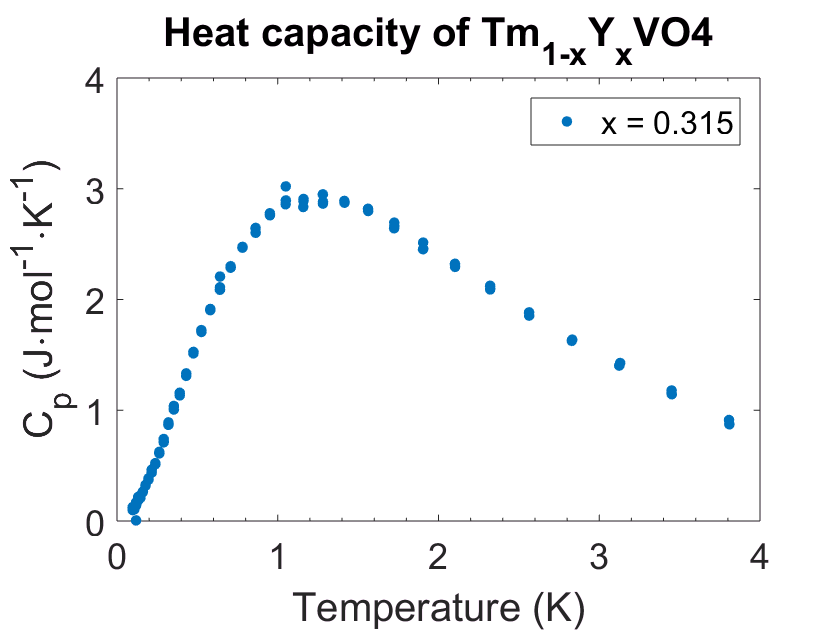

plotCpDoping(split,dpg,1,L,ttlCpY)

# Average data

## Sort each dataset by increasing value of temperature

for i=1:L
    srtd{i} = sortrows(split{i},{'T'});
%     [split{i}.T,wo] = sort(split{i}.T);
%     split{i}.Cp = split{i}.Cp(wo);
end
srtd = srtd';

## Test the temperature scattering between data points supposedly taken at the "same" temperature

4mK is the empirical maximal dispersion of data points taken consecutively at a given temperature. In order to check this, one can run the following code on the temperature variable T:

nrep = 3;% number of repetitions of the measurement at each temperature
% We want to compute the temperature separation between two data points
% that are NOT repetitions of the same measurement
Tsep = 4e-3;% value of temperature separation to be tested, in Kelvin
% Data points taken within an interval of Tsep are considered to be measured at the same temperature setpoint
for i = 1
    for k = 1:length(srtd{i}.T)-nrep
        if abs(srtd{i}.T(k+nrep)-srtd{i}.T(k))<Tsep
% if the values of temperature for two data points supposedly
% measured at two different temperature setpoints are separated by less than Tsep
            srtd{i}.T(k);% display the value of temperature for the first data point
        end
    end
end

IF this piece of code outputs one or more values AND IF these values obviously correspond to measurements that were supposed to be measured at different temperature setpoints, THEN reduce Tsep in order to reach a value for which the code does not output anything.

## Compute average of data points taken

for i = 1:L
    Tm = [];Cpm = [];stdCpm = [];% initialize temporary tables;
    k = 1;% initiliaze loop index k
    while k<length(srtd{i}.T)% loop over k
        ind = [k];% initialize temporary table of indices
        j = k+1;% initialize subloop index 
        while abs(srtd{i}.T(j)-srtd{i}.T(k))<Tsep
            % loop over datapoints within a temperature interval of Tsep
            % i.e. datapoints measured at the same temperature setpoint
            ind = [ind, j];% store index of current datapoint
            j = j+1;% increase subloop index
            if j>= length(srtd{i}.T)% safety condition
                break
            end
        end
        if length(ind)>1% do not include isolated data points
            Tm = [Tm,mean(srtd{i}.T(ind))];% average of temperature for data points
            % taken at the same temperature setpoint
            Cpm = [Cpm,mean(srtd{i}.Cpmol(ind))];% average of heat capacity
            stdCpm = [stdCpm,std(srtd{i}.Cpmol(ind))];% standard deviation of heat capacity
        end
        k = j+1;% once all datapoints measured at the same temperature setpoints are averaged,
        % increase the main loop index in order to jump to the next data point measured
        % at a different temperature setpoint
    end
    avgData(i).T = Tm;% store the full averaged temperature table
    avgData(i).Cp = Cpm;% store the full averaged heat capacity table
    avgData(i).stdCp = stdCpm;% store the full table of standard deviation of heat capacity
end

## Plot averaged Cp data for YTmVO4 x<xc

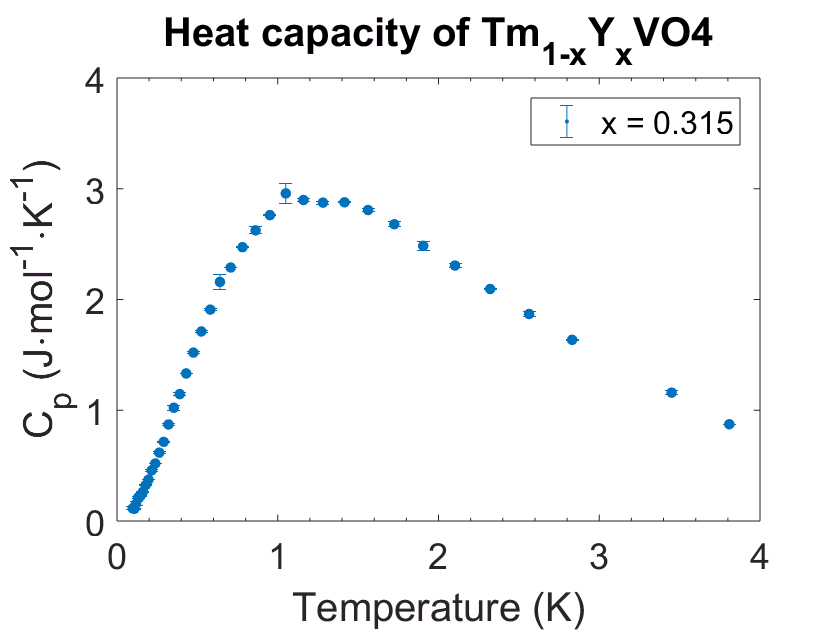

plotAvgCp(avgData,dpg,1,1)
title(ttlCpY)

# Temperature derivative of heat capacity

## Compute dCp/dT

ylbldCp = 'dC_p / dT (J\cdotmol^{-1}\cdotK^{-2})';
ttldCp = 'dC_p / dT of Tm_{1-x}Y_xVO4';
close;figure
for i=1:L
    avgData(i).dCp = diff(avgData(i).Cp)';% differential of Cp
    avgData(i).dT = diff(avgData(i).T');% differential of T
    avgData(i).Tm = mean([avgData(i).T(1:end-1);avgData(i).T(2:end)])';% in order ot have the same # of data points as in dCp
    avgData(i).derCp = avgData(i).dCp ./ avgData(i).dT;% temperature derivative of Cp
end

## Plot dCp/dT for YTmVO4

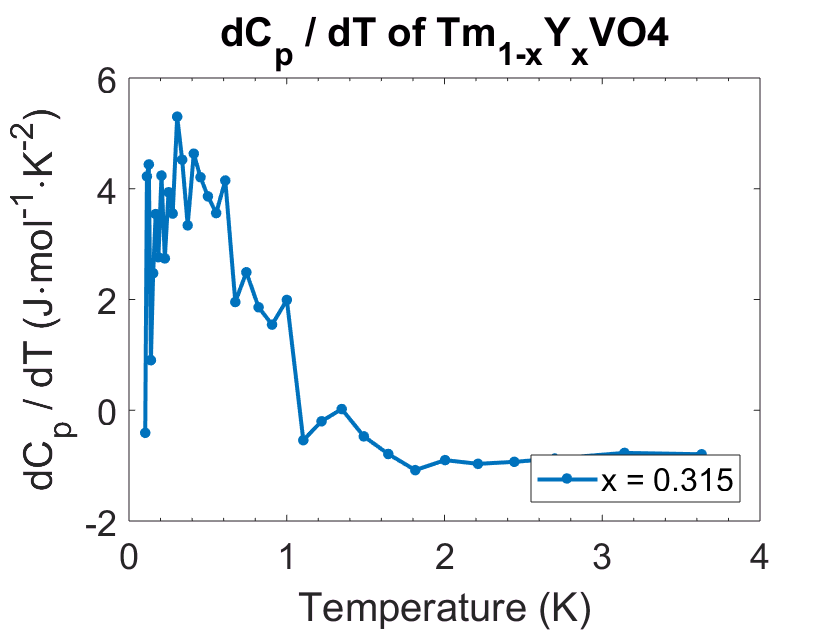

close;figure
for i=1:L
    plot(avgData(i).Tm,avgData(i).derCp,'.-','MarkerSize',18,'DisplayName',['x = ',num2str(dpg(i))])
    hold on
end
xlabel(xlblTemp);ylabel(ylbldCp);title(ttldCp);legend('show','Location','southeast');

# Fit data by temperature regimes

## Separate temperature regimes

% lowTdata(1) = IndexedStructCopy(avgData(1),(avgData(1).T<0.5));
lowTtemp = avgData(1).T(avgData(1).T<0.5);
lowTCp = avgData(1).Cp(avgData(1).T<0.5);% increases as T^1.6
highTtemp = avgData(1).T(avgData(1).T>1.6);
highTCp = avgData(1).Cp(avgData(1).T>1.6);% decreases as T^-2

# Fitting data with complex Schottky anomaly

%% Fit: 'Schottky anomaly'.
[xData, yData] = prepareCurveData(avgData(1).T,avgData(1).Cp);


## Single Schottky anomaly

% Set up single Schottky fittype and options.
ftsingle = fittype('b*(a/x)^2.*sech(a/x)^2', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.987660083686466 0.237061969477491];% a,b,mu,sgm in this order
opts.Lower = [0 0];

% Fit "single Schottky" model to data.
[fitressingle, gof] = fit( xData, yData, ftsingle, opts );
Coeffssingle = coeffvalues(fitressingle)

Coeffssingle =     1.2577    7.4145


## Normal distribution of Schottky anomalies

% Set up normal distribution of Schottky fittype and options.
ftnorm = fittype('b*(normpdf(a,mu,sgm)/x)^2.*sech(normpdf(a,mu,sgm)/x)^2', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.987660083686466 0.237061969477491 1 1];% a,b,mu,sgm in this order
opts.Lower = [0 0 0 0];
% opts.Upper = [Inf Inf Inf Inf];

% Fit normal distribution of Schottky model to data.
[fitresnorm, gof] = fit( xData, yData, ftnorm, opts );
Coeffsnorm = coeffvalues(fitresnorm)

Coeffsnorm =     1.2923    7.4144    1.2931    0.3172


## Normal distribution of Schottky anomalies

% Set up normal distribution of Schottky fittype and options.
ftnorm2 = fittype('b*normpdf(((a)/x)^2.*sech(a/x)^2,mu,sgm)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.987660083686466 0.237061969477491 1 1];% a,b,mu,sgm in this order
opts.Lower = [0 0 0 0];
% opts.Upper = [Inf Inf Inf Inf];

% Fit normal distribution of Schottky model to data.
[fitresnorm2, gof] = fit( xData, yData, ftnorm2, opts );
Coeffsnorm2 = coeffvalues(fitresnorm2)

Coeffsnorm2 =     1.2732    1.5135    0.4047    0.2166


## "free" Lorentz fit

% Set up normal distribution of Schottky fittype and options.
ftlorentz = fittype('a*x^b/(x^c+d)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1 1 1 1];% a,b,mu,sgm in this order
opts.Lower = [0 0 0 0];
% opts.Upper = [Inf Inf Inf Inf];

% Fit normal distribution of Schottky model to data.
[fitreslorentz, gof] = fit( xData, yData, ftlorentz, opts );
disp(['CoeffsLorentz names',coeffnames(ftlorentz)'])

    'CoeffsLorentz names'    'a'    'b'    'c'    'd'



Coeffslorentz = coeffvalues(fitreslorentz)

Coeffslorentz =     7.7748    1.4543    2.8964    1.6929


## Plot data + fits

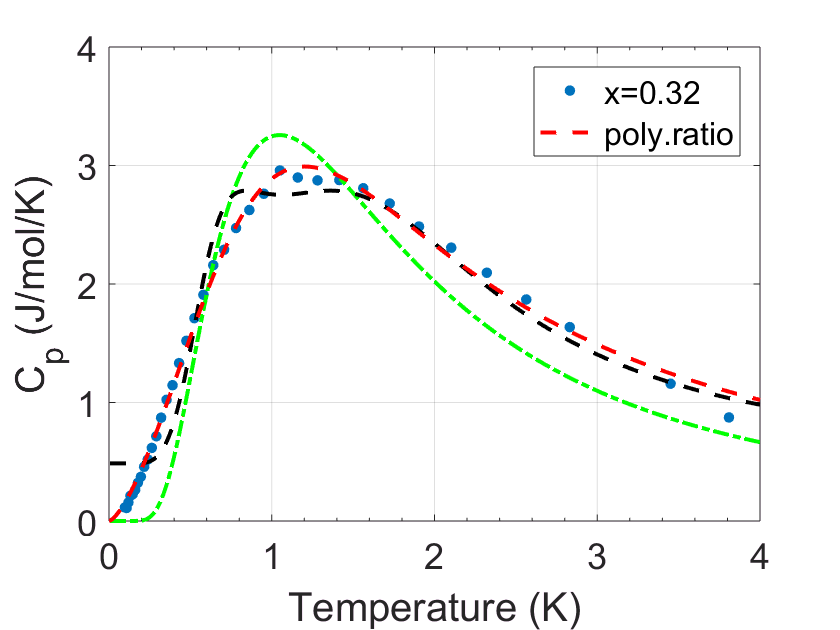

% Plot fit with data.
figure( 'Name', 'Schottky anomaly' );
p0 = plot(xData, yData,'.' , 'markers',18);%,'DisplayName','x=0.32'
hold on
plot(fitressingle,'--');
plot(fitresnorm,'--g');
plot(fitresnorm2,'--k');
% plot(fitreslorentz,'--k','DisplayName','polyratio');
p4 = plot(fitreslorentz,'--r');
% legend('x=0.32','single','normal','poly.ratio', 'Location', 'NorthEast' );
legend([p0,p4],{'x=0.32','poly.ratio'});
% Label axes
xlabel('Temperature (K)')
ylabel('C_p (J/mol/K)')
grid on